# Spoofing Detection (Detection Algorithms)

addpath(genpath(fileparts(which('pathfile.m'))))
interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);
set(groot, 'defaultAxesTickLabelInterpreter',interr);
set(groot, 'defaultLegendInterpreter',interr);
c = 299792458;
L1freq = 1575.42e6;
Re = 6378137;
if ~exist('clean')
    spoofingdetection
end
if ~exist('brdcind')
    brdc = loadRINEXNavigation('G','data','brdc2580.12n');
end

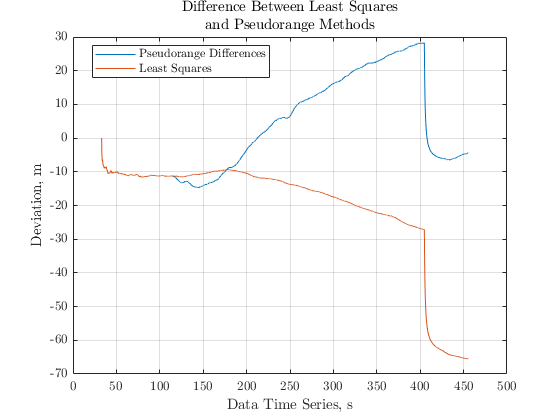

[~,brdcind] = ismember(prnnums,brdc.sat);
GPStime = ORT - dR/c; GPStime = mod(GPStime,24*3600);
GPStime2 = [ORT_weeksec(:,1), ORT_weeksec(:,2)-dR/c];
wgs = wgs84Ellipsoid;
UTECEF = [mean(x_cs),mean(y_cs),mean(z_cs)];
[UTGEO(1),UTGEO(2),UTGEO(3)] = ECEF2GEODETIC(UTECEF);
alpha = [0.1490D-07  0.2235D-07 -0.1192D-06 -0.1192D-06];
beta = [0.1085D+06  0.6554D+05 -0.1966D+06 -0.1311D+06];
timeind = 7;
for i = 1:length(prnnums)
    % sat position from ephemeris
    eph = brdc.eph{brdcind(i)}(:,timeind);
    a = eph(22);
    ecc = eph(20);
    TGD(i) = eph(37);
    svbias(i) = eph(12);
    [posT{i},aux{i}] = getSatPosGPS(ORT_weeksec,eph);
    Ek = aux{i}(:,timeind);
    posR{i} = rotPos(posT{i}(:,1),posT{i}(:,2),posT{i}(:,3),prange(:,i)/c);
    LLA{i} = ecef2lla(posR{i},'WGS84');
%     [AER{i}(:,1),AER{i}(:,2),~] = ecef2aer(posR{i}(:,1),posR{i}(:,2),posR{i}(:,3),UTGEO(1),UTGEO(2),UTGEO(3),wgs);
    iono(:,i) = klobmodel(UTGEO(1),UTGEO(2),az_cs(:,i),el_cs(:,i),GPStime,alpha,beta);
    trop(:,i) = saastamoinen(.44,300,1011,UTGEO(1),UTGEO(2),UTGEO(3),az_cs(:,i),el_cs(:,i));
    trel(:,i) =  getSVRelativityClockCorrection('G',a,ecc,Ek);
end

n = length(prnnums);
prange_corr = prange - iono - trop - c*(TGD - svbias - trel);
prange_corr_cs = prange_cs - iono - trop - c*(TGD - svbias - trel);

for i = 1:length(prnnums)
    prange_sdiff(:,i) = diff(prange_corr(:,i));
end

LS = navsolLS([x_cs(1)-40;y_cs(1)-64;z_cs(1)+20],prange_corr_cs,posR,GPStime,prnnums);
start = [LS(1,1),LS(1,2),LS(1,2)];
est = navsolPD(GPStime,prnnums,posR,prange_corr,start,dR,"PD");
est_cs = navsolPD(GPStime,prnnums,posR,prange_corr_cs,start,dR,'PD');

plot(plottime,(est(:,1)-LS(:,1)))
hold on
plot(plottime,(est_cs(:,1)-LS(:,1)))
title(["Difference Between Least Squares" ,...
    "and Pseudorange Methods"])
legend('Pseudorange Differences','Least Squares','Location',"best"  )
grid on
xlabel('Data Time Series, s')
ylabel('Deviation, m')